# Figure 2 - Linearity and comparison with de Veld

The main figure will have have one or two subjects illustrating linearity as we scale the light intensity.  We may include signal to noise w.r.t. reflectance.  There will also be a panel showing how well we fit a weighted sum of the data from our four subjects onto the deVeld subject.

ieInit;
waves = 500:5:700;
symbols = {'kx-','k*-','k^-','ko-'};

T = oeDatabaseCreate;
theSubject = 'Z';

## Subject 1 (Z) excitation light 405 

Read in the files at all excitation levels

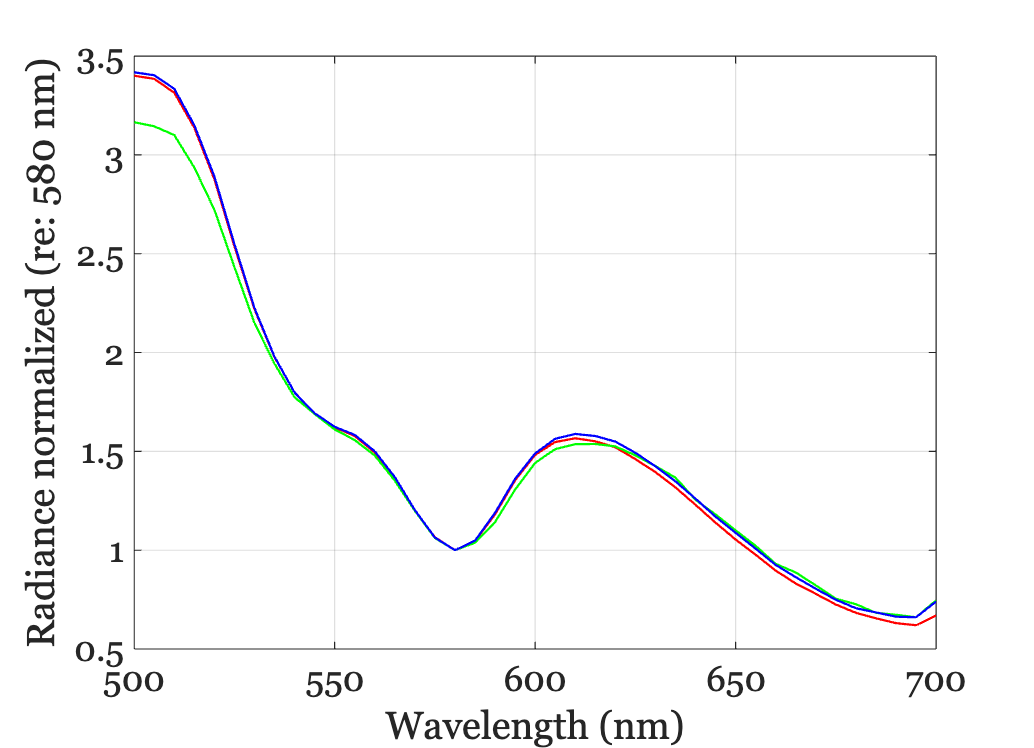

eWave = 405;
[files405,tRows405] = ieTableGet(T,'subject',theSubject,...
    'substrate','lip', ...
    'ewave',eWave, ...
    'date','2024-03-14');

data = oeReadFiles(files405,'waves',waves,'normalized wave',580);
ieFigure;
plot(waves,data);
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');
grid on;

## Subject 1 (Z) excitation light 415 

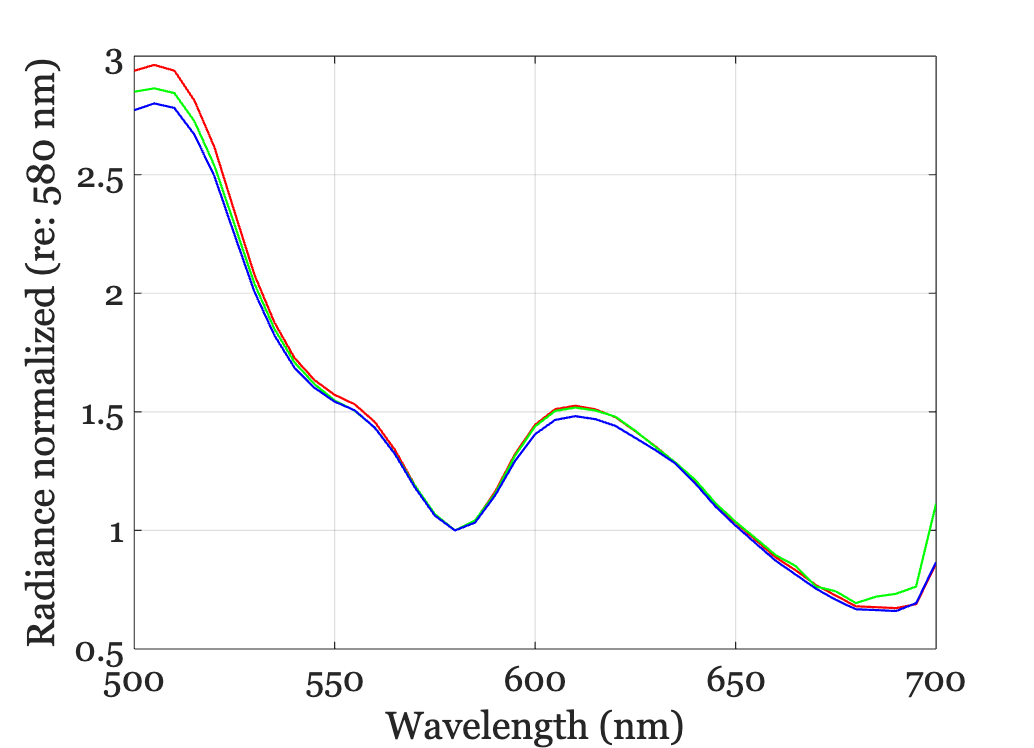

eWave = 415;
files415 = ieTableGet(T,'subject',theSubject,...
    'substrate','lip', ...
    'ewave',eWave, ...
    'date','2024-03-14');

data = oeReadFiles(files415,'waves',waves,'normalized wave',580);
ieFigure;
plot(waves,data);
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');
grid on;

## Subject 1 (Z) Lip excitation light 450

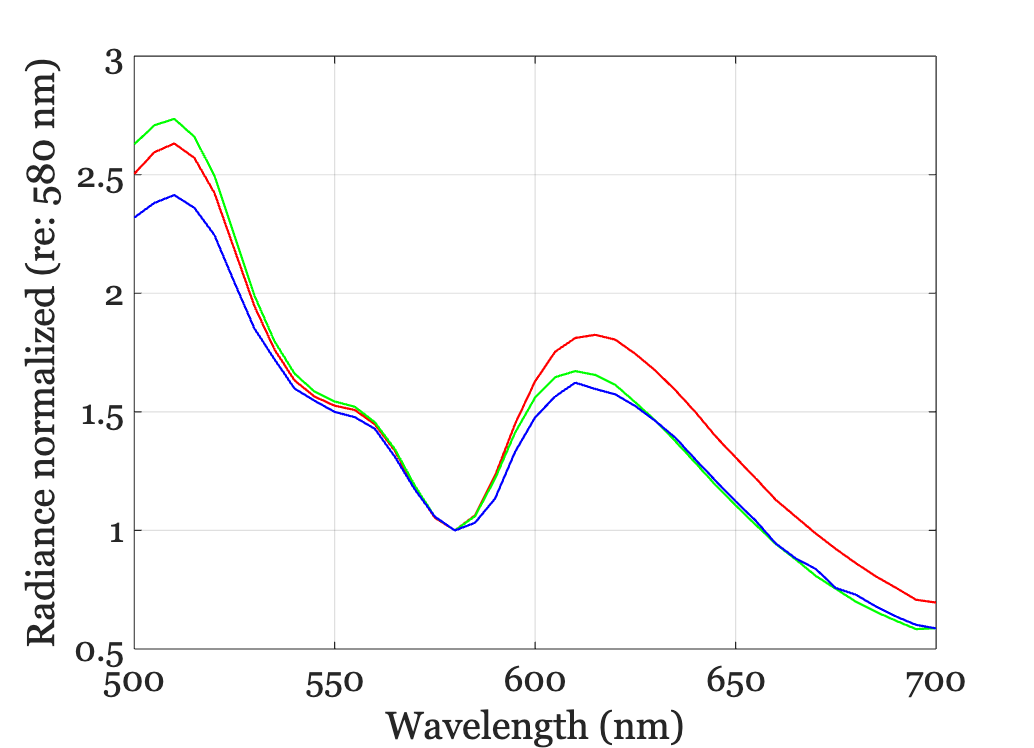

eWave = 450;
files450 = ieTableGet(T,'subject',theSubject,...
    'substrate','lip', ...
    'ewave',eWave, ...
    'date','2024-03-14');

data = oeReadFiles(files450,'waves',waves,'normalized wave',580);

ieFigure;
plot(waves,data);
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');
grid on;

## Pooled excitations

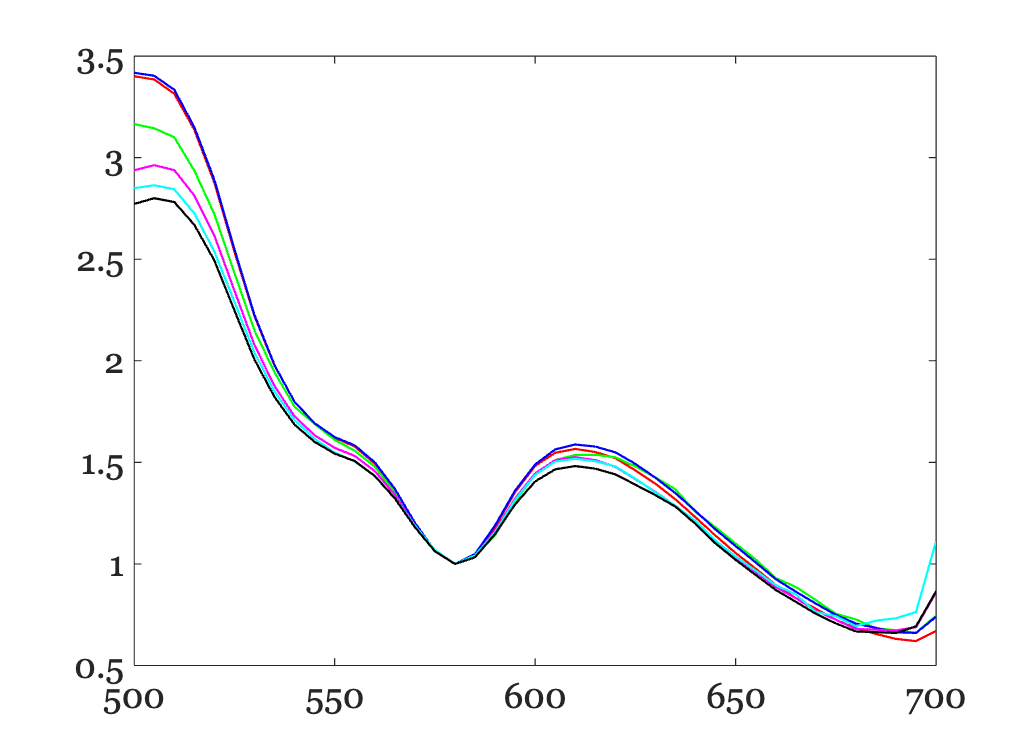

pooled = cat(1,files405,files415);
data = oeReadFiles(pooled,'waves',waves,'normalized wave',580);
plot(waves,data);

## Subject 1 (Z) Tongue excitation light 405 

Read in the files at all excitation levels

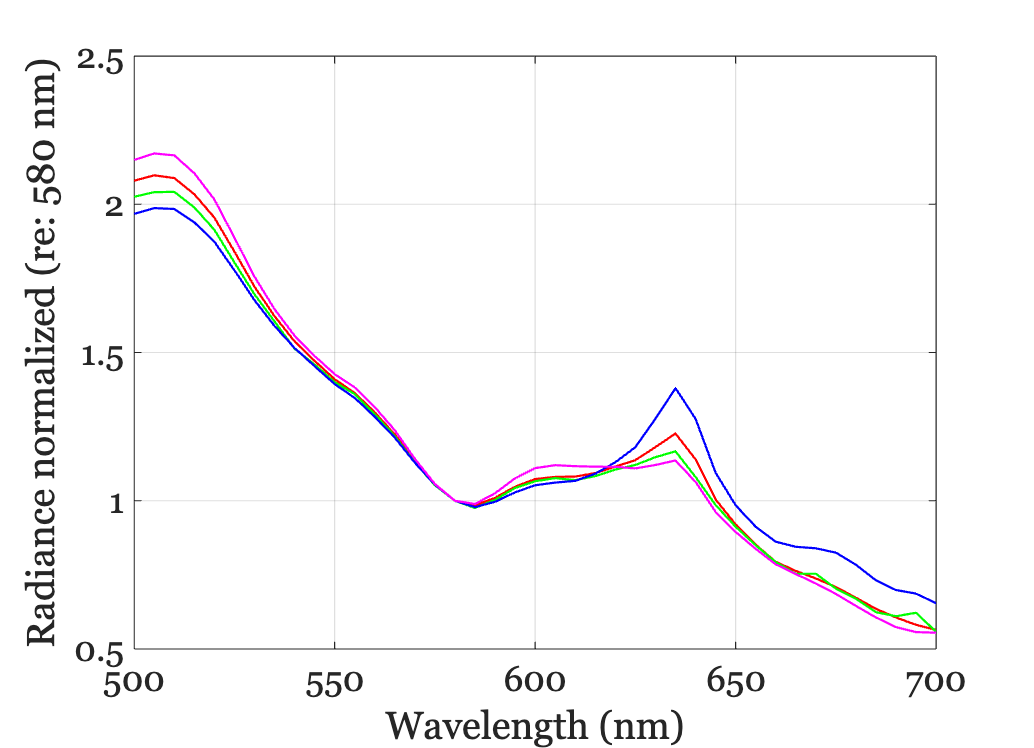

eWave = 405;
files405 = ieTableGet(T,'subject',theSubject,...
    'substrate','tongue', ...
    'ewave',eWave); %, ...
    % 'date','2024-03-14');

data = oeReadFiles(files405,'waves',waves,'normalized wave',580);
ieFigure;
plot(waves,data);
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');
grid on;

## Subject 1 (Z) Tongue excitation light 415 

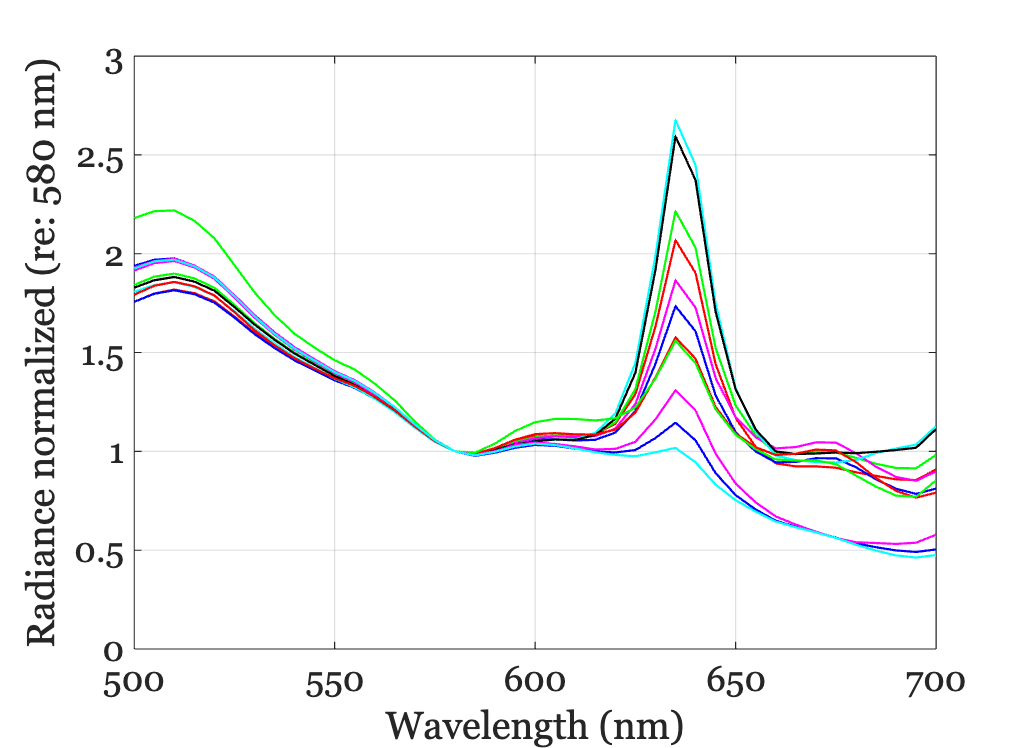

eWave = 415;
files415 = ieTableGet(T,'subject',theSubject,...
    'substrate','tongue', ...
    'ewave',eWave); %, ...
    % 'date','2024-03-14');

data = oeReadFiles(files415,'waves',waves,'normalized wave',580);

ieFigure;
plot(waves,data);
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');
grid on;

## Subject 1 (Z) Tongue excitation light 450

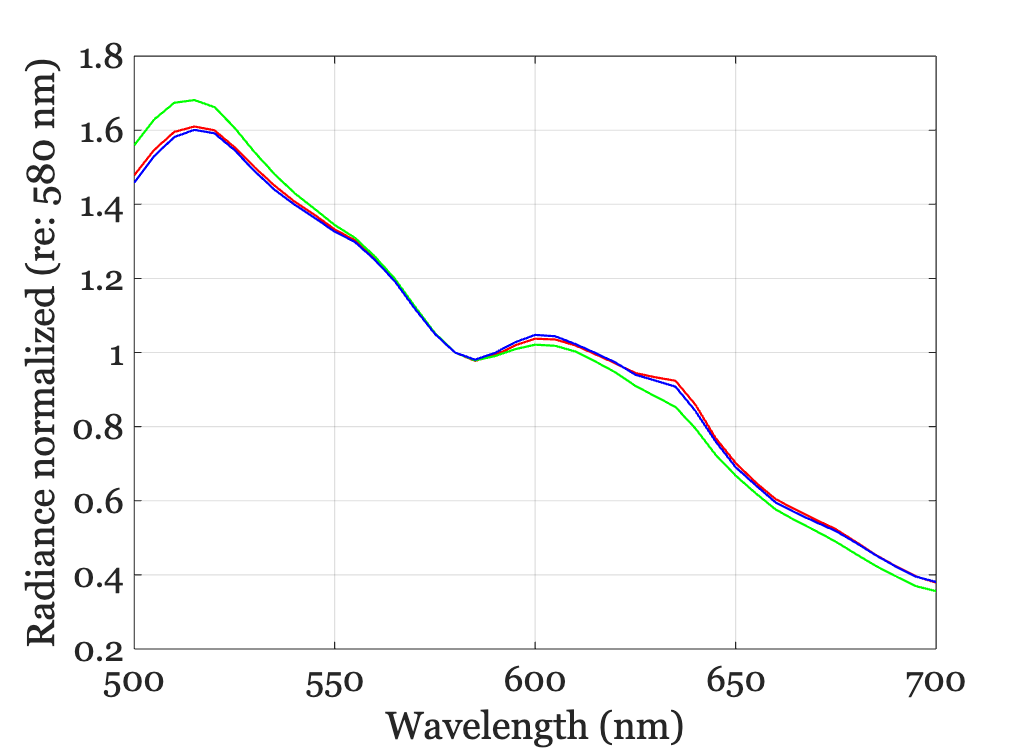

eWave = 450;
files450 = ieTableGet(T,'subject',theSubject,...
    'substrate','tongue', ...
    'ewave',eWave); % , ...
    % 'date','2024-03-14');

data = oeReadFiles(files450,'waves',waves,'normalized wave',580);

ieFigure;
plot(waves,data);
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');
grid on;

## Pooled excitations

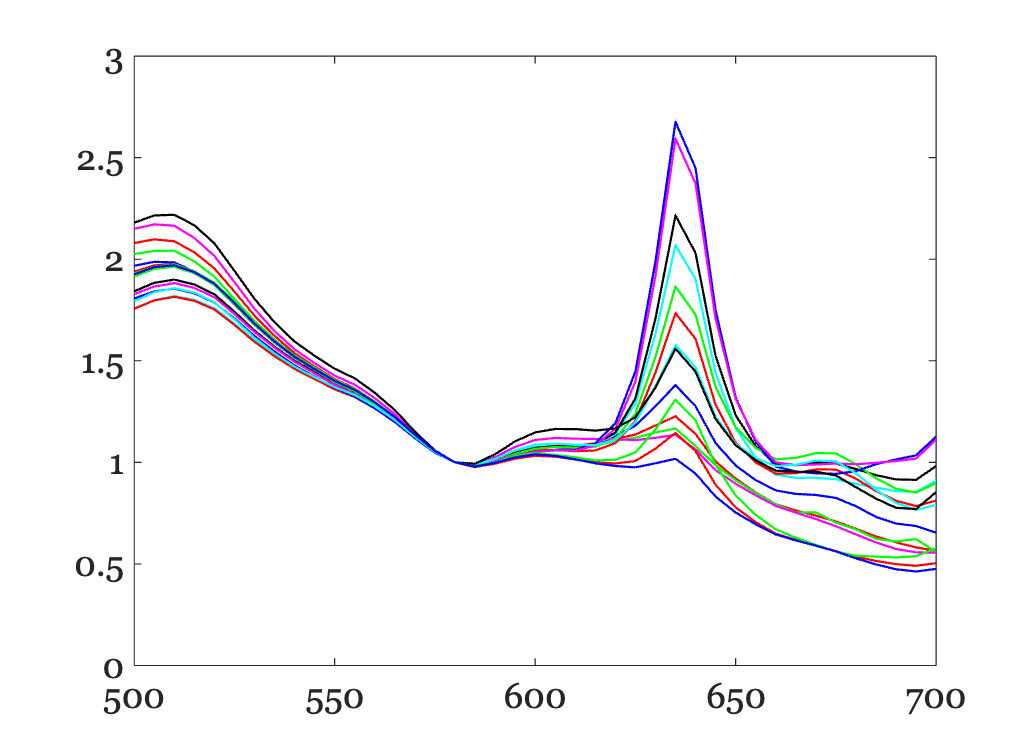

pooled = cat(1,files405,files415);
data = oeReadFiles(pooled,'waves',waves,'normalized wave',580);
plot(waves,data);